## **Tworzenie bazy danych.**

Edycja plików audio w celu stworzenia bazy danych.

clearvars
[AudioCel, FsC] = audioread("cello.wav");
[AudioFlu, FsF] = audioread("flety.wav");
[AudioPia, FsP] = audioread("piano.wav");
Fs = 44100;

%podział nagrań na fragmenty 0.1s
length = Fs/10; 
audioCelRaw = reshape(AudioCel(1:10000*length),length,[]);
audioFluRaw = reshape(AudioFlu(1:10000*length),length,[]);
audioPiaRaw = reshape(AudioPia(1:10000*length),length,[]);

%zmienne używane do stworzenia bazy danych spektrogramów
audioData = cat(2,audioCelRaw,audioFluRaw,audioPiaRaw);
labels(1:10000) = "cel";
labels(10001:20000) = "flu";
labels(20001:30000) = "pia";

Tworzenie bazy danych - spektrogramow.

parfor i = 1:10000 %wiolonczele
    data = audioData(:,i);
    % Generowanie spektrogramu,parametry ustawiono tak, by uwidocznić 
    % ważne w analizie detale (nawet po zmniejszeniu rozdzielczości).
    spektrogram = spectrogram(data, hamming(64), 32, 1000, Fs); 
    % Zmiana rozmiaru na analizowany przez sieć AlexNet, pozwala
    % zaoszczędzić pamięc i przyspieszyć zapis
    spekRes = imresize(spektrogram,[227,227]);

    figure('Visible', 'off');
    imagesc(log10(abs(spekRes)));
    axis off

    % Zapisanie spektrogramu jako .jpg
    fpath = "SpectDataMade\" + labels(i);
    filename = strrep(string(i), '.wav', '.jpg');
    saveas(gcf, fullfile(fpath, filename), 'jpg');
    close;
end

parfor i = 10001:20000 %flety

    data = audioData(:,i);
    spektrogram = spectrogram(data, hamming(64), 32, 1000, Fs);
    spekRes = imresize(spektrogram,[227,227]);

    figure('Visible', 'off');
    imagesc(log10(abs(spekRes)));
    axis off

    fpath = "SpectDataMade\" + labels(i);
    filename = strrep(string(i), '.wav', '.jpg');
    saveas(gcf, fullfile(fpath, filename), 'jpg');
    close;
end

parfor i = 20001:30000 %pianina

    data = audioData(:,i);
    spektrogram = spectrogram(data, hamming(64), 32, 1000, Fs);
    spekRes = imresize(spektrogram,[227,227]);

    figure('Visible', 'off');
    imagesc(log10(abs(spekRes)));
    axis off

    fpath = "SpectDataMade\" + labels(i);
    filename = strrep(string(i), '.wav', '.jpg');
    saveas(gcf, fullfile(fpath, filename), 'jpg');
    close;
end

## Szkolenie sieci

Stworzenie Datastore - pozwala odwyływać się do poszczególnych elementów bazy danych przez adresy co przyspiesza dalsze operacje

spds = imageDatastore("SpectDataMade", "IncludeSubfolders",true,'LabelSource','foldernames')

spds =   ImageDatastore with properties:

                       Files: {
                              ' ...\Projekt Michal Zienkowicz Bartosz Trela\SpectDataMade\cel\1.jpg';
                              ' ...\Projekt Michal Zienkowicz Bartosz Trela\SpectDataMade\cel\10.jpg';
                              ' ...\Projekt Michal Zienkowicz Bartosz Trela\SpectDataMade\cel\100.jpg'
                               ... and 30181 more
                              }
                     Folders: {
                              ' ...\Matlab_DL\Projekt Michal Zienkowicz Bartosz Trela\SpectDataMade'
                              }
                      Labels: [cel; cel; cel ... and 30181 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadF

Stworzenie zbioru treningowego oraz testowego. AugmentedImageDatastore służy do zmiany obrazów na RGB - format wymagany przez sieć Alex (rozmiar został zmieniony w pentlach tworzących bazę)

[trainImgs,testImgs] = splitEachLabel(spds,0.80);
trainData = augmentedImageDatastore([227 227],trainImgs);
testData = augmentedImageDatastore([227 227],testImgs);

Użyta sieć - AlexNet - sieć przetrenowana do analizy obrazów. Późniejsze modyfikacje pozwolą osiągnąć lepsze wyniki.

net = alexnet;
im = imread("SpectDataMade\cel\31.jpg"); %przykładowy spektrogram
conv = activations(net,im,'conv1'); %conv1 - odpowiada za pierwszą warstwę.
imshow(imtile(rescale(conv))) %pozwala przyjżeć się jak poszczególne.

trainFeatures = activations(net,trainData,'fc7','OutputAs','rows');
classifier = fitcnb(trainFeatures,trainImgs.Labels);

testFeatures = activations(net,testData,'fc7','OutputAs','rows'); %aktywacje warstwy fc7 (fully connected 7)
predLabels = predict(classifier,testFeatures);
numCorrect = nnz(predLabels==testImgs.Labels);
accuracy = numCorrect/numel(predLabels) %celność z jaką model rozpoznaje instrumenty zawarte w bazie danych

accuracy = 0.7247

confusionchart(testImgs.Labels,predLabels); %pozwala zaobserwować jakich błedów model popełnia najwięcej

conv5 = activations(net,im,'fc7');
imshow(imtile(rescale(conv))) %pozwala przyjżeć się jak poszczególne.

Dobranie lepszych parametrów optymalizatora Adam.

trainingOptions('adam') %wyświetlenie podstawowych parametrów

ans =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-03
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 30
                   MiniBatchSize: 128
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'once'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
            ExecutionEnvironment: 'a

Stworzenie nowej sieci na podstawie sieci alexnet w celu poprawienia działania oraz jej wyszkolenie

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:07 |       28.12% |       2.6028 |      1.0000e-04 |
|       1 |          50 |       00:00:34 |       86.72% |       0.3131 |      1.0000e-04 |
|       1 |         100 |       00:01:01 |       98.44% |       0.0696 |      1.0000e-04 |
|       1 |         150 |       00:01:28 |       96.09% |       0.1433 |      1.0000e-04 |
|       2 |         200 |       00:01:55 |       99.22% |       0.0653 |      1.0000e-04 |
|       2 |         250 |       00:02:21 |       95.31% |       0.1367 |      1.0000e-04 |
|       2 |         300 |  

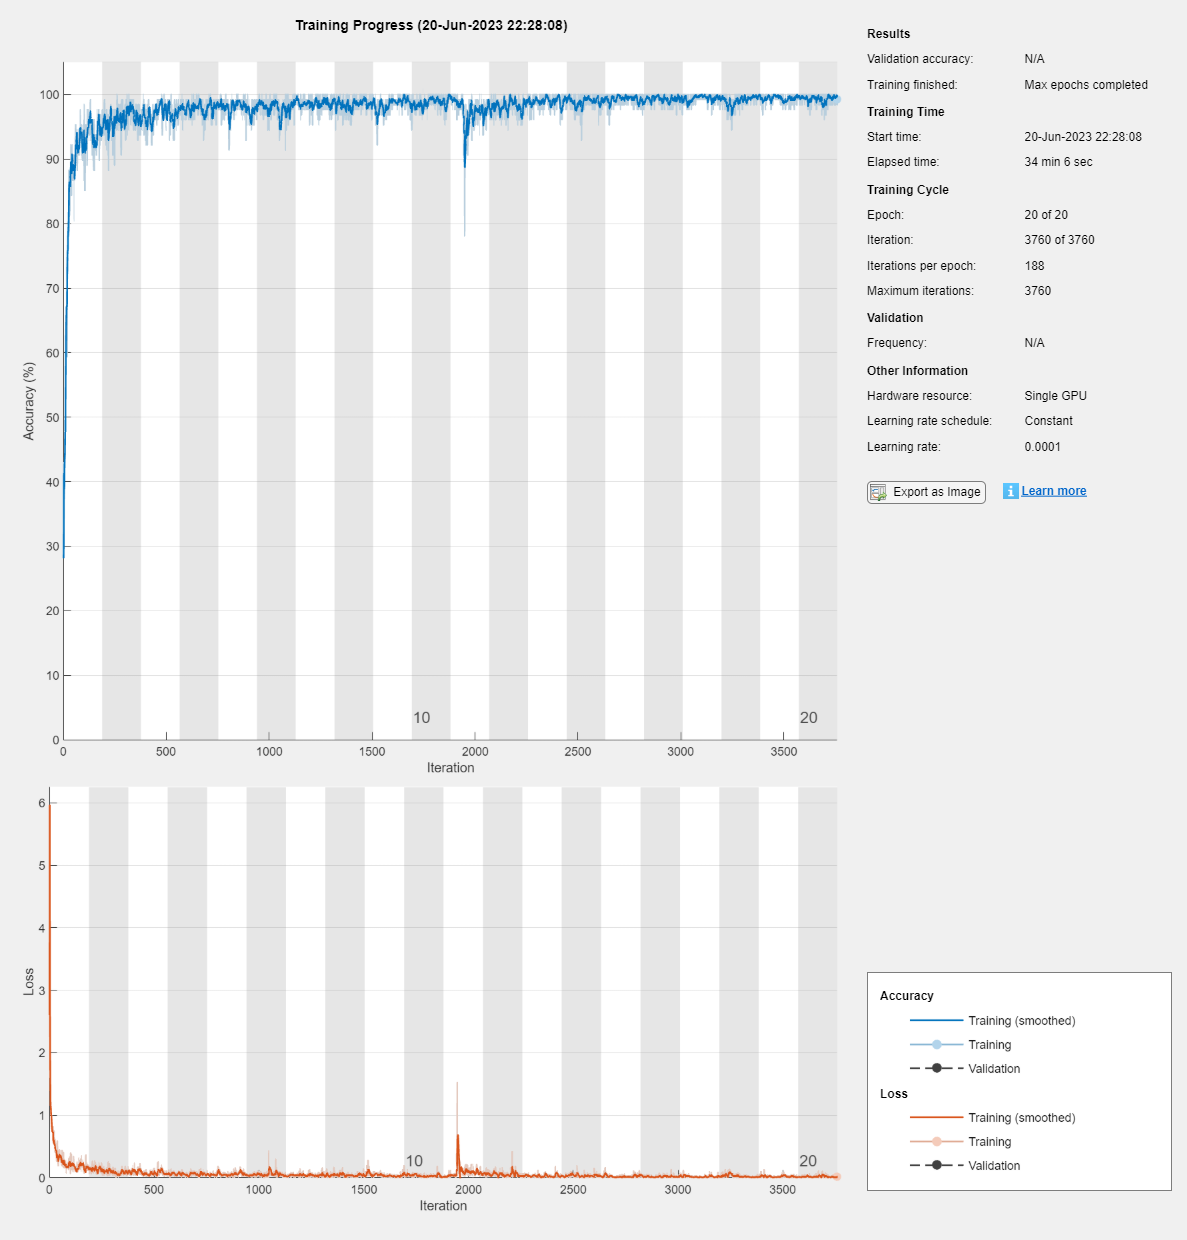

net = alexnet;
layers = net.Layers;
layers(end-2) = fullyConnectedLayer(3);
layers(end) = classificationLayer();
options = trainingOptions("adam", ... % wytłumaczenie wyboru zmienianych parametrów w prezentacji
    "plots","training-progress", ...
    "InitialLearnRate",0.0001, ...
    "MaxEpochs",20);
spectnet = trainNetwork(trainData,layers,options);


trainFeatures = activations(spectnet,trainData,'fc7','OutputAs','rows');
classifier = fitcnb(trainFeatures,trainImgs.Labels);

testFeatures = activations(spectnet,testData,'fc7','OutputAs','rows'); 
predLabels = predict(classifier,testFeatures);
numCorrect = nnz(predLabels==testImgs.Labels);
accuracy = numCorrect/numel(predLabels) 

accuracy = 0.9385

confusionchart(testImgs.Labels,predLabels); 

Druga poprawka do sieci w celu wyeliminowania przeszkalania się modeli

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:02 |       28.12% |       2.3766 |      1.0000e-04 |
|       1 |          50 |       00:00:29 |       86.72% |       0.3357 |      1.0000e-04 |
|       1 |         100 |       00:00:57 |       92.19% |       0.2198 |      1.0000e-04 |
|       1 |         150 |       00:01:25 |       92.97% |       0.1408 |      1.0000e-04 |
|       2 |         200 |       00:01:52 |       96.09% |       0.1558 |      1.0000e-04 |
|       2 |         250 |       00:02:20 |       98.44% |       0.0629 |      1.0000e-04 |
|       2 |         300 |  

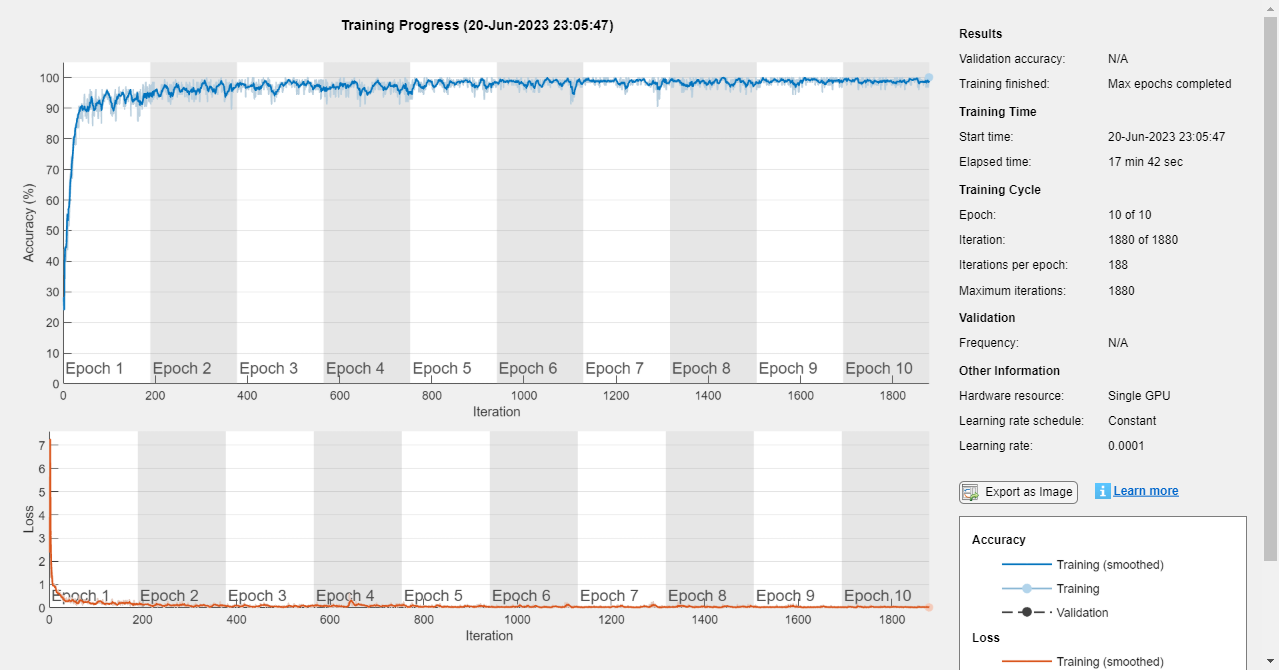

net = alexnet;
layers = net.Layers;
layers(end-2) = fullyConnectedLayer(3);
layers(end) = classificationLayer();
options = trainingOptions("adam", ...
    "plots","training-progress", ...
    "InitialLearnRate",0.0001, ...
    "MaxEpochs",10); %Zmiana MaxEpochs z 20 na 10
spectnet = trainNetwork(trainData,layers,options);


trainFeatures = activations(spectnet,trainData,'fc7','OutputAs','rows');
classifier = fitcnb(trainFeatures,trainImgs.Labels);

testFeatures = activations(spectnet,testData,'fc7','OutputAs','rows'); 
predLabels = predict(classifier,testFeatures);
numCorrect = nnz(predLabels==testImgs.Labels);
accuracy = numCorrect/numel(predLabels) 

accuracy = 0.9238

confusionchart(testImgs.Labels,predLabels); 